Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    16



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0013



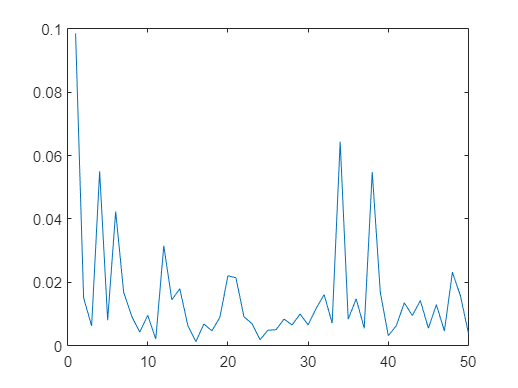

hold off;


net1 = fitnet(16,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 16
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

[net1,tr1] = train(net1,pn,tn);

output_ANN1 = net1(pn)

output_ANN1 =     0.5009    0.4954    0.5141    0.5352    0.5412    0.5557    0.5361    0.5475    0.5588    0.7091    0.7144    0.7110    0.7310    0.7055    0.7038    0.7402    0.7262    0.7123    0.9161    0.9284    0.9215    0.9155    0.9179    0.9356    0.9492    0.9553    0.9684    1.0058    0.9982    0.9843    0.1944    0.1821    0.1937    0.1865    0.1739    0.1689    0.3423    0.3215    0.3099    0.3088    0.3042    0.3159    0.3113    0.3054    0.3147    0.4303    0.4251    0.4174    0.4194    0.4306
    0.0332    0.5253    0.7428    0.0699    0.4658    0.7919    0.1162    0.4427    0.7692    0.0352    0.6168    0.6638    0.0450    0.4772    0.7023    0.1222    0.4597    0.7972    0.0498    0.7142    0.5517    0.0200    0.4959    0.5727    0.1218    0.4649    0.6705    0.0113    0.6437    0.5566    0.0806    0.5503    0.7024    0.1461    0.5221    0.8046    0.1051    0.7575    0.5321    0.0525    0.6003    0.6060    0.1266    0.5182    0.6608    0.0230    0.7638    0.4295    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   117.6227  117.0496  119.0065  121.2133  121.8392  123.3622  121.3100  122.4991  123.6882  139.4047  139.9609  139.6081  141.7035  139.0290  138.8559  142.6581  141.2006  139.7430  161.0602  162.3520  161.6248  161.0041  161.2527  163.1069  164.5236  165.1623  166.5358  170.4484  169.6456  168.1969   85.5679   84.2771   85.4878   84.7415   83.4194   82.8939  101.0407   98.8557   97.6455   97.5356   97.0461   98.2755   97.7956   97.1712   98.1507  110.2394  109.6935  108.8895  109.1024  110.2701


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.7789    1.5110    1.8345    0.8336    1.4225    1.9075    0.9024    1.3881    1.8737    0.7820    1.6470    1.7170    0.7965    1.4394    1.7742    0.9114    1.4134    1.9154    0.8037    1.7919    1.5502    0.7594    1.4672    1.5815    0.9108    1.4211    1.7270    0.7463    1.6870    1.5575    0.8495    1.5482    1.7744    0.9470    1.5062    1.9264    0.8860    1.8563    1.5210    0.8077    1.6225    1.6309    0.9180    1.5004    1.7125    0.7638    1.8657    1.3685    0.8089    1.7928


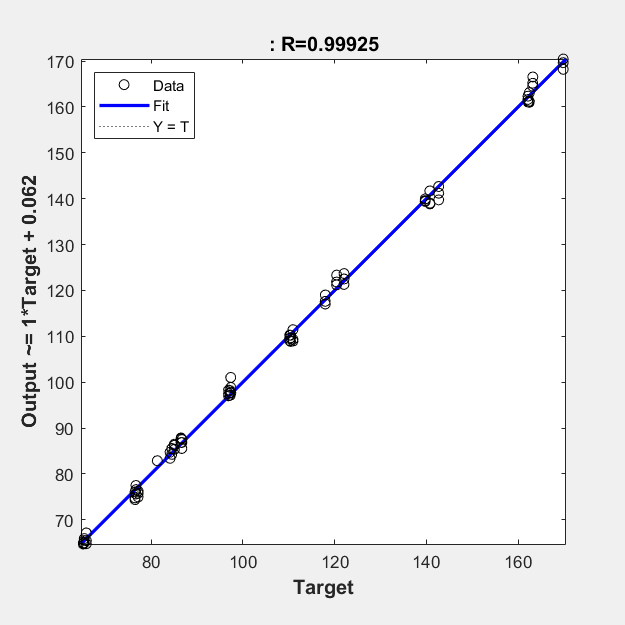

plotregression(t1,ANNIPF)

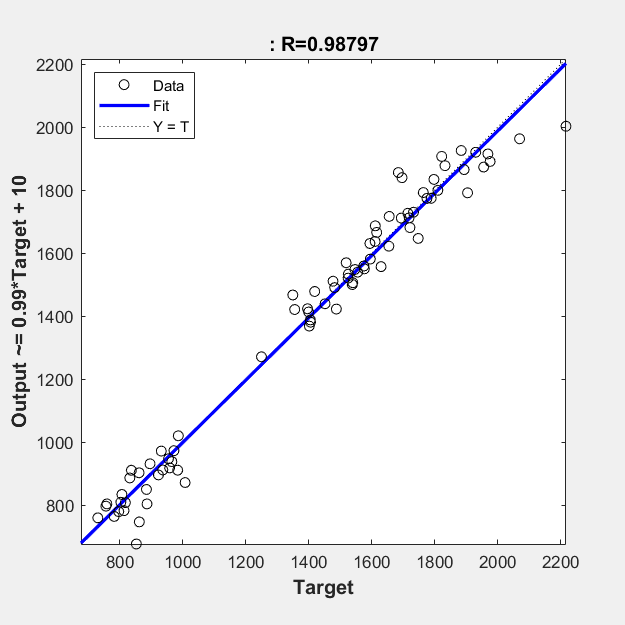

plotregression(t2,ANNSEA)

%plotregression(t1,output_ANN1(1,:));
%plotregression(t2,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.7033
    0.4865



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 138.7970

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.4532e+03

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.